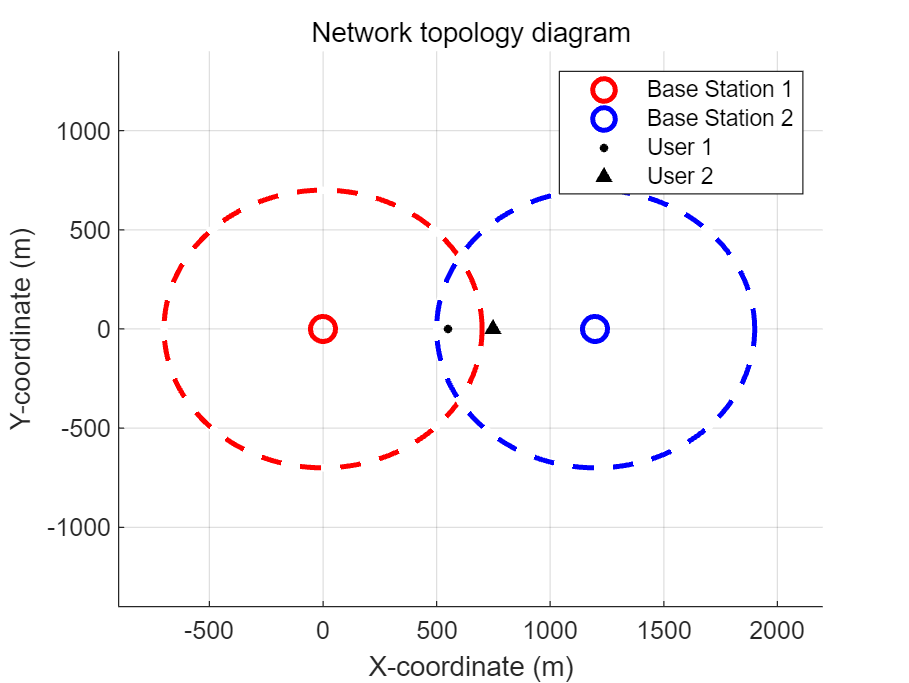

clear; clc; close all;

% Define the position of UE and BS
bs1_pos = [0, 0];  
bs2_pos = [1200, 0]; 
radius = 700;    
ue1_pos = [550, 0];
ue2_pos = [750, 0];    
numSlots = 1000;       % timeslots
maxdatarate = 2;       % packet/slot
lambda = [0.75, 1.5, 2.5];% different loads

% Network toplogy
figure;
hold on; grid on;
plot(bs1_pos(1), bs1_pos(2), 'ro', 'MarkerSize',10,'LineWidth',2); 
plot(bs2_pos(1), bs2_pos(2), 'bo', 'MarkerSize',10,'LineWidth',2); 
viscircles(bs1_pos, radius, 'Color','r','LineStyle','--');        
viscircles(bs2_pos, radius, 'Color','b','LineStyle','--');        
plot(ue1_pos(1), ue1_pos(2), 'k*','MarkerSize',3,'LineWidth',2);   
plot(ue2_pos(1), ue2_pos(2), 'k^','MarkerSize',3,'LineWidth',2);  
title('Network topology diagram');                               
xlabel('X-coordinate (m)'); ylabel('Y-coordinate (m)');          
legend('Base Station 1', 'Base Station 2', 'User 1', 'User 2'); 
xlim([-900 2200]);
ylim([-1400 1400]);
hold off;

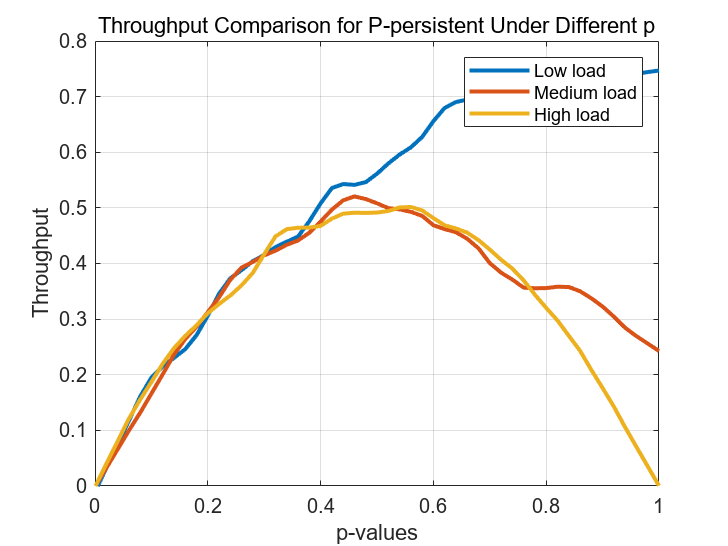


% Define 3 methods and loads
methods = {'Uncoordinated', 'QLBS', 'P-persistent'};
loadfig = {lambda(1), lambda(2), lambda(3)};


% SINR
P_tx1 = 30;  % transimission power of BS1
P_tx2 = 30;  % BS2
dbs1_1 = norm(bs1_pos-ue1_pos);    % distance from BS1-UE1
dbs2_1 = norm(bs2_pos-ue1_pos);    % BS2-UE2
dbs1_2 = norm(bs1_pos-ue2_pos);  
dbs2_2 = norm(bs2_pos-ue2_pos); 
d0 = 1; 
alpha = 3; 
N0 = 1e-21; 
B = 1e7;   
calc_power = @(dist, PL0, exp,d0) 10^((PL0+10*exp*log10(d0/dist))/10); % calculate power


x_range = linspace(-100, 300, 100); 
y_range = linspace(-radius, radius, 100); 
[X, Y] = meshgrid(x_range, y_range);

SINR_with_BS2 = zeros(size(X));
SINR_without_BS2 = zeros(size(X)); 

% calculate SINR
for i = 1:size(X, 1)
    for j = 1:size(X, 2)

        d1 = sqrt((X(i, j) - bs1_pos(1))^2 + (Y(i, j) - bs1_pos(2))^2);
        d2 = sqrt((X(i, j) - bs2_pos(1))^2 + (Y(i, j) - bs2_pos(2))^2);

        
        P_s = calc_power(d1, P_tx1, alpha, d0); 
        P_i = calc_power(d2, P_tx2, alpha, d0); 
        P_n = N0 * B * rand(); 

        SINR_with_BS2(i, j) = 10 * log10(P_s / (P_i + P_n));
        P_i = 0; % only BS1 work
        SINR_without_BS2(i, j) = 10 * log10(P_s / (P_i + P_n));
    end
end

%Test different p
p_values = 0:0.02:1;
throughput_p = zeros(length(p_values), 3);
delay_p = zeros(length(p_values), 3);


for p_index = 1:length(p_values)
    p_persistent = p_values(p_index); 

    
    for loadIdx = 1:length(lambda) % 3 loads
        arrivalRate = lambda(loadIdx); 

        queueBS1 = poissrnd(arrivalRate, 1, numSlots);
        queueBS2 = poissrnd(arrivalRate, 1, numSlots);

        % initialize
        transmitBS1 = zeros(1, numSlots);
        transmitBS2 = zeros(1, numSlots);
        transmitstatusBS1 = zeros(3, numSlots);
        transmitstatusBS2 = zeros(3, numSlots);
        delay1 = zeros(3, 1);
        delay2 = zeros(3, 1);

        for method = 1:3 % 3 methods
            queue1 = cumsum(queueBS1); % BS1 queue length
            queue2 = cumsum(queueBS2); % BS2
            
            for t = 1:numSlots % time slots
                if method == 1 % Uncoordinated method
                    if queue1(t) >= maxdatarate && queue2(t) >= maxdatarate
                        transmitBS1(t) = maxdatarate;
                        transmitBS2(t) = maxdatarate;
                    elseif queue1(t) >= maxdatarate
                        transmitBS1(t) = maxdatarate;
                        transmitBS2(t) = queue2(t);
                    elseif queue2(t) >= maxdatarate
                        transmitBS1(t) = queue1(t);
                        transmitBS2(t) = maxdatarate;
                    else
                        transmitBS1(t) = queue1(t);
                        transmitBS2(t) = queue2(t);
                    end
                elseif method == 2 % QLBS method
                    if queue1(t) > 0 && queue2(t) > 0
                        if queue1(t) > queue2(t)
                            transmitBS1(t) = min(queue1(t), maxdatarate);
                            transmitBS2(t) = 0;
                        elseif queue1(t) < queue2(t)
                            transmitBS2(t) = min(queue2(t), maxdatarate);
                            transmitBS1(t) = 0;
                        else
                            if rand > 0.5
                                transmitBS1(t) = min(queue1(t), maxdatarate);
                                transmitBS2(t) = 0;
                            else
                                transmitBS2(t) = min(queue2(t), maxdatarate);
                                transmitBS1(t) = 0;
                            end
                        end
                    else
                        if queue1(t) > 0 && queue2(t) == 0
                            transmitBS1(t) = min(queue1(t), maxdatarate);
                            transmitBS2(t) = 0;
                        elseif queue1(t) == 0 && queue2(t) > 0
                            transmitBS2(t) = min(queue2(t), maxdatarate);
                            transmitBS1(t) = 0;
                        else
                            transmitBS1(t) = 0;
                            transmitBS2(t) = 0;
                        end
                    end
                elseif method == 3 % P-persistent method
                    if rand > p_persistent
                        transmitBS1(t) = 0; 
                    else 
                        if queue1(t) > maxdatarate
                            transmitBS1(t) = maxdatarate;
                        else
                            transmitBS1(t) = queue1(t);
                        end
                    end
                    if rand > p_persistent
                        transmitBS2(t) = 0;
                    else 
                        if queue2(t) > maxdatarate
                            transmitBS2(t) = maxdatarate;
                        else
                            transmitBS2(t) = queue2(t);
                        end
                    end
                end 
                %% SINR check before update
                if transmitBS1(t) > 0
                    P_s = calc_power(dbs1_1, P_tx1, alpha, d0); 
                    if transmitBS2(t) > 0
                        P_i = calc_power(dbs2_1, P_tx2, alpha, d0); 
                    else
                        P_i = 0;
                    end
                    P_n = N0 * B * rand(); 
                    SINR_ue1 = 10 * log10(P_s / (P_i + P_n));
                    if SINR_ue1 < 5
                        % SINR lower than 5dB，failed
                        transmitBS1(t) = 0;
                    end
                end

                queue1(1,:) = queue1(1,:) - transmitBS1(t); % update queue 1
                queue2(1,:) = queue2(1,:) - transmitBS2(t); 
                delay1(method,1) = delay1(method,1) + queue1(t); 
                delay2(method,1) = delay2(method,1) + queue2(t);
            end
            transmitstatusBS1(method,:) = transmitBS1;
            transmitstatusBS2(method,:) = transmitBS2;
        end
        loadcell1{loadIdx} = transmitstatusBS1;
        loadcell2{loadIdx} = transmitstatusBS2;
        delaycell1{loadIdx} = delay1;
        delaycell2{loadIdx} = delay2;
    end

    % calculate throughput
    throughput = zeros(3, 3);
    for loadindex = 1:3
        for methodIndex = 1:3
            load1 = loadcell1{loadindex};
            loadrow1 = load1(methodIndex,:);
            load2 = loadcell2{loadindex};
            loadrow2 = load2(methodIndex,:);
            throughput(loadindex,methodIndex) = sum(loadrow1) / numSlots;
        end
    end

    % calculate delay
    delay_results = zeros(3, 3);
    for loadindex = 1:3
        load1 = delaycell1{loadindex};
        delay_results(loadindex,:) = load1;
        delay_results(loadindex,:) = delay_results(loadindex,:) ./ (throughput(loadindex,:) .* numSlots);
    end

    % performance under p
    throughput_p(p_index,:) = throughput(:,3)'; 
    delay_p(p_index,:) = delay_results(:,3)';   

end

% smoothing
throughput_p_smooth = zeros(size(throughput_p));
for i = 1:3
    throughput_p_smooth(:, i) = smooth(throughput_p(:, i), 0.1, 'lowess'); % 使用LOWESS平滑方法
end

delay_p_smooth = zeros(size(delay_p));
for i = 1:3
    delay_p_smooth(:, i) = smooth(delay_p(:, i), 0.1, 'lowess');
end

% plot throughput figure
figure;
plot(p_values, throughput_p_smooth(:,1), 'DisplayName', 'Low load', 'LineWidth', 2);
hold on;
plot(p_values, throughput_p_smooth(:,2), 'DisplayName', 'Medium load', 'LineWidth', 2);
plot(p_values, throughput_p_smooth(:,3), 'DisplayName', 'High load', 'LineWidth', 2);
xlabel('p-values');
ylabel('Throughput');
title('Throughput Comparison for P-persistent Under Different p');
grid on;
legend;
hold off;
xlim([0.000 1.000])
ylim([0.000 0.800])

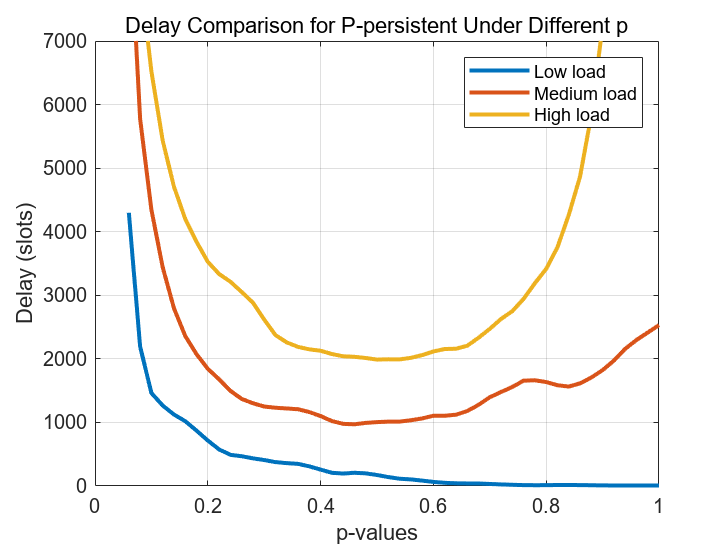


% plot delay figure
figure;
plot(p_values, delay_p_smooth(:,1), 'DisplayName', 'Low load', 'LineWidth', 2);
hold on;
plot(p_values, delay_p_smooth(:,2), 'DisplayName', 'Medium load', 'LineWidth', 2);
plot(p_values, delay_p_smooth(:,3), 'DisplayName', 'High load', 'LineWidth', 2);
xlabel('p-values');
ylabel('Delay (slots)');
title('Delay Comparison for P-persistent Under Different p');
grid on;
legend;
hold off;
xlim([0.000 1.000])
ylim([0.000 7000])